syms w u(t) x(t) r(t) h(t) y(t)
u(t) = heaviside(t);
x(t) = u(t-2); 
h(t) =  (-t+2).*(u(t)-u(t-2))

$$h(t) = \left(t-2\right)\,\left(\mathrm{heaviside}\left(t-2\right)-\mathrm{heaviside}\left(t\right)\right)$$

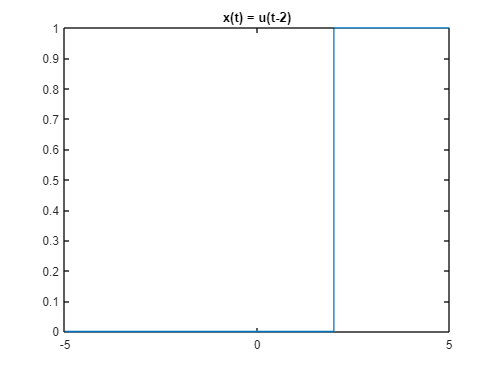

y(t) = int(x(w)*h(t-w), w, -inf, inf);
fplot(x(t))
title('x(t) = u(t-2)')

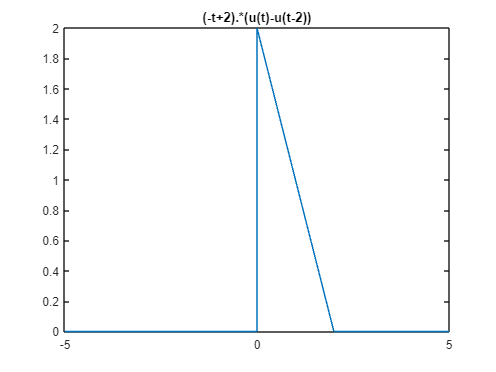

fplot(h(t))
title('(-t+2).*(u(t)-u(t-2))')

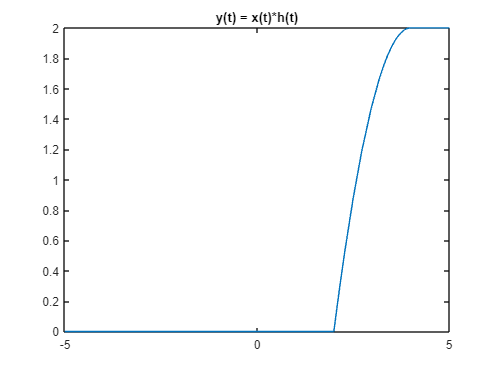

fplot(y(t))
title('y(t) = x(t)*h(t)')